**Tarea 4: aplicación de un VQ previamente entrenado**

load('Tarea3.mat')
addpath('./datos')
addpath('./funciones')

Considera los ficheros tvg_training_20s.wav y tvg_test_20s.wav.

%[valores_training, fs_training] = audioread('tvg_training_20s.wav');
%[valores_test, fs_test] = audioread('tvg_test_20s.wav');

Compara las distorsiones obtenidas al aplicar VQ6 sobre el conjunto de vectores de entrenamiento y de test.

    % y: matriz con los vectores resultantes de la cuantificación

    % Dist: Error cuadrático medio entre la dimensión del vector.

    % x : matriz con vectores a cuantificar por fila.

    % VQ: Matriz con los centroides del VQ por filas.

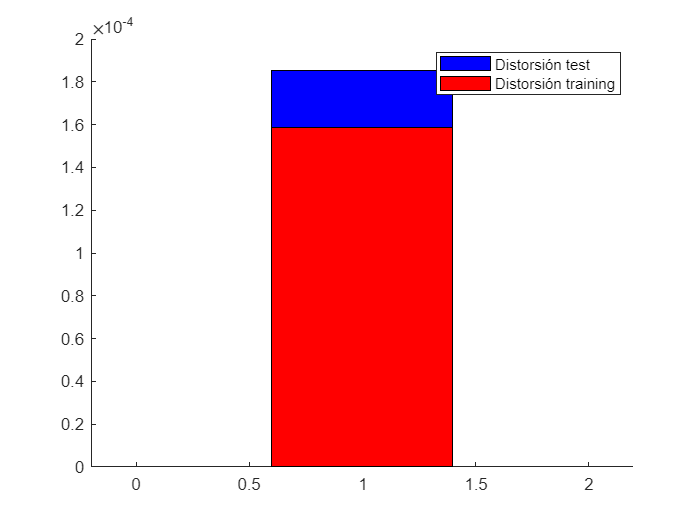

%load('traindata.mat')
if isempty(gcp('nocreate'))
parpool;
end

[y_training, Dist_training] = VQuantize(training,VQ6);
[y_test, Dist_test] = VQuantize(test,VQ6);

hold on
bar(Dist_test,'b')
bar(Dist_training,'r')
legend('Distorsión test', 'Distorsión training')
hold off

columna = 0; %reordenar en una fila el audio
fila = 1;
for i=1:length(valores_training)
    if columna == 0 %impar
        testReordenado (i) = y_test(fila, 1);
        columna = 1;
    else %par
        testReordenado (i) = y_test(fila, 2);
        columna = 0;
        fila = fila + 1;
    end
end

columna = 0; %reordenar en una fila el audio
fila = 1;
for i=1:length(valores_test)
    if columna == 0 %impar
        trainingReordenado (i) = y_training(fila, 1);
        columna = 1;
    else %par
        trainingReordenado (i) = y_training(fila, 2);
        columna = 0;
        fila = fila + 1;
    end
end

%sound(testReordenado, fs_training*2)

%sound(trainingReordenado, fs_training*2)

SNRtest = SNR(valores_test, testReordenado)

SNRtest = 16.4854

SNRtraining = SNR(valores_training, trainingReordenado)

SNRtraining = 15.8174

save Tarea4.mat